% FM Code
clear all; clc; clf;
% INSTRUCTIONS

### Modulation

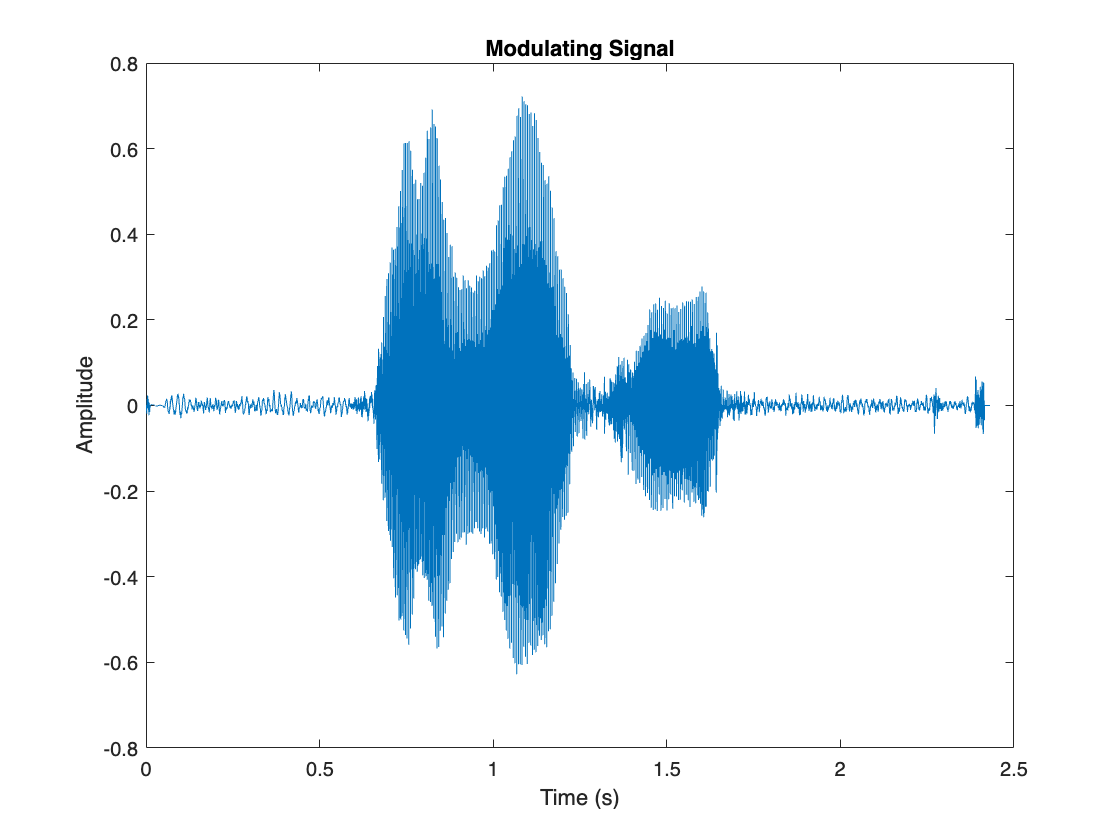

% Step 1: Generate a modulating signal
[y, Fs] = audioread('New-Recording.wav');
sound(y,Fs)
% scope = spectrumAnalyzer(SampleRate = Fs);
t = linspace(0, length(y)/Fs, length(y));
figure;
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Modulating Signal');

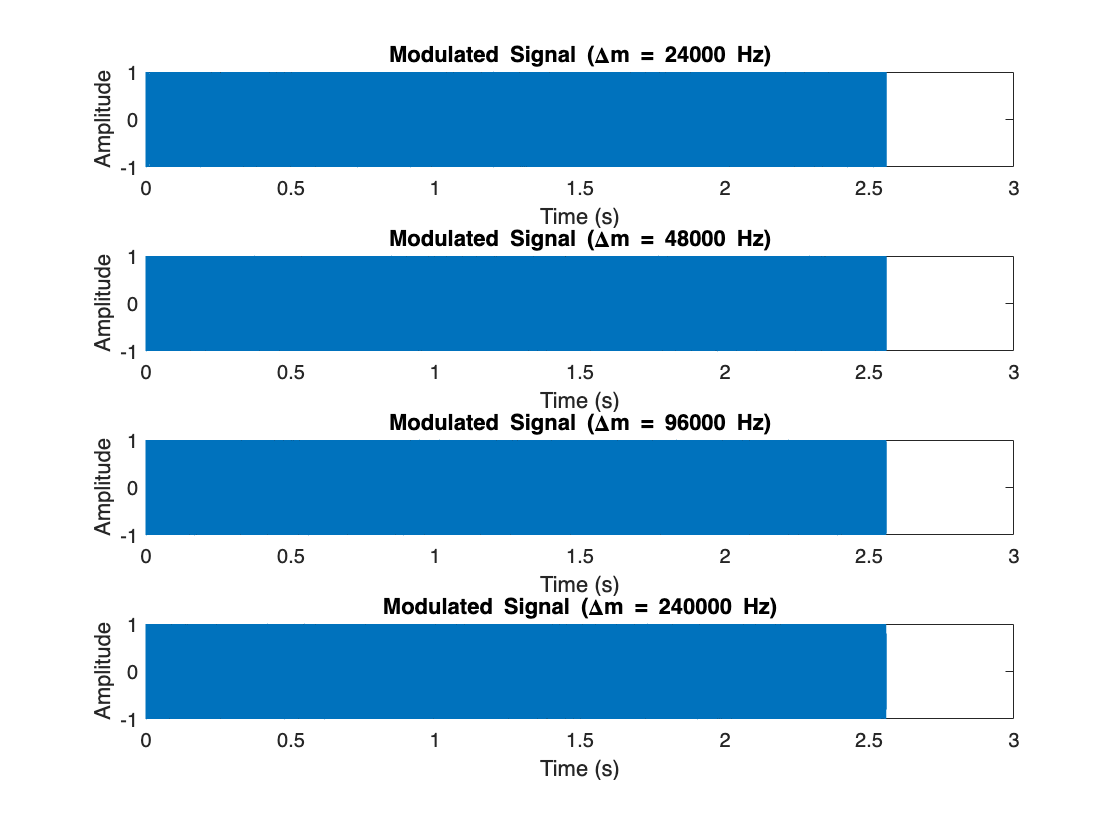

% Step 2: Apply Frequency Modulation
Fc = Fs/2; % Carrier frequency

% Set frequency deviations under test
devf1 = Fs*0.5;
devf2 = Fs*1;
devf3 = Fs*2;
devf4 = Fs*5;

% Apply frequency modulation
y_fmmod1 = fmmod(y,Fc,Fs,devf1);
y_fmmod2 = fmmod(y,Fc,Fs,devf2);
y_fmmod3 = fmmod(y,Fc,Fs,devf3);
y_fmmod4 = fmmod(y,Fc,Fs,devf4);

figure;
subplot(411)
plot(t, y_fmmod1); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf1) ' Hz)']);
subplot(412)
plot(t, y_fmmod2); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf2) ' Hz)']);
subplot(413)
plot(t, y_fmmod3); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf3) ' Hz)']);
subplot(414)
plot(t, y_fmmod4); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf4) ' Hz)']);

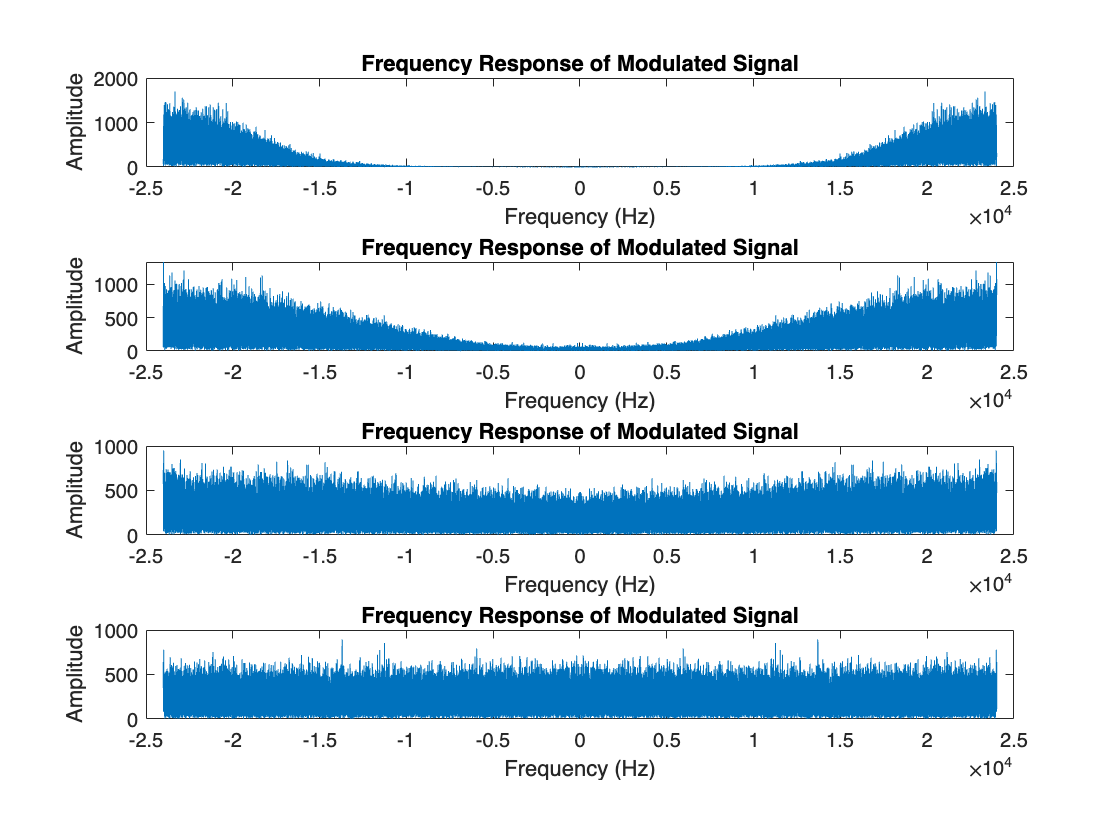

figure;
subplot(411)
fftplot(y_fmmod1,Fs)
subplot(412)
fftplot(y_fmmod2,Fs)
subplot(413)
fftplot(y_fmmod3,Fs)
subplot(414)
fftplot(y_fmmod4,Fs)

% Step 3: Amplify the modulated signals
Gfm = 100;
y_afmmod1 = Gfm*y_fmmod1;
y_afmmod2 = Gfm*y_fmmod2;
y_afmmod3 = Gfm*y_fmmod3;
y_afmmod4 = Gfm*y_fmmod4;

#### During Transmission

% Step 4: Add noise
% Define SNR values (in dB)
snr1 = 0;
snr2 = 2;
snr3 = 5;
snr4 = 10;
snr5 = -2;
snr6 = -5;
snr7 = -10;

% Apply additive white gaussian noise
% For m = 0.5,
y_nafmmod11 = awgn(y_afmmod1,snr1);
y_nafmmod12 = awgn(y_afmmod1,snr2);
y_nafmmod13 = awgn(y_afmmod1,snr3);
y_nafmmod14 = awgn(y_afmmod1,snr4);
y_nafmmod15 = awgn(y_afmmod1,snr5);
y_nafmmod16 = awgn(y_afmmod1,snr6);
y_nafmmod17 = awgn(y_afmmod1,snr7);

% For m = 1,
y_nafmmod21 = awgn(y_afmmod2,snr1);
y_nafmmod22 = awgn(y_afmmod2,snr2);
y_nafmmod23 = awgn(y_afmmod2,snr3);
y_nafmmod24 = awgn(y_afmmod2,snr4);
y_nafmmod25 = awgn(y_afmmod2,snr5);
y_nafmmod26 = awgn(y_afmmod2,snr6);
y_nafmmod27 = awgn(y_afmmod2,snr7);

% For m = 2,
y_nafmmod31 = awgn(y_afmmod3,snr1);
y_nafmmod32 = awgn(y_afmmod3,snr2);
y_nafmmod33 = awgn(y_afmmod3,snr3);
y_nafmmod34 = awgn(y_afmmod3,snr4);
y_nafmmod35 = awgn(y_afmmod3,snr5);
y_nafmmod36 = awgn(y_afmmod3,snr6);
y_nafmmod37 = awgn(y_afmmod3,snr7);

% For m = 5,
y_nafmmod41 = awgn(y_afmmod4,snr1);
y_nafmmod42 = awgn(y_afmmod4,snr2);
y_nafmmod43 = awgn(y_afmmod4,snr3);
y_nafmmod44 = awgn(y_afmmod4,snr4);
y_nafmmod45 = awgn(y_afmmod4,snr5);
y_nafmmod46 = awgn(y_afmmod4,snr6);
y_nafmmod47 = awgn(y_afmmod4,snr7);

### Demodulation

% Step 5: Demodulate
% For m = 0.5,
y_fmdemod11 = fmdemod(y_nafmmod11,Fc,Fs,devf1);
y_fmdemod12 = fmdemod(y_nafmmod12,Fc,Fs,devf1);
y_fmdemod13 = fmdemod(y_nafmmod13,Fc,Fs,devf1);
y_fmdemod14 = fmdemod(y_nafmmod14,Fc,Fs,devf1);
y_fmdemod15 = fmdemod(y_nafmmod15,Fc,Fs,devf1);
y_fmdemod16 = fmdemod(y_nafmmod16,Fc,Fs,devf1);
y_fmdemod17 = fmdemod(y_nafmmod17,Fc,Fs,devf1);

% For m = 1,
y_fmdemod21 = fmdemod(y_nafmmod21,Fc,Fs,devf2);
y_fmdemod22 = fmdemod(y_nafmmod22,Fc,Fs,devf2);
y_fmdemod23 = fmdemod(y_nafmmod23,Fc,Fs,devf2);
y_fmdemod24 = fmdemod(y_nafmmod24,Fc,Fs,devf2);
y_fmdemod25 = fmdemod(y_nafmmod25,Fc,Fs,devf2);
y_fmdemod26 = fmdemod(y_nafmmod26,Fc,Fs,devf2);
y_fmdemod27 = fmdemod(y_nafmmod27,Fc,Fs,devf2);

% For m = 2,
y_fmdemod31 = fmdemod(y_nafmmod31,Fc,Fs,devf3);
y_fmdemod32 = fmdemod(y_nafmmod32,Fc,Fs,devf3);
y_fmdemod33 = fmdemod(y_nafmmod33,Fc,Fs,devf3);
y_fmdemod34 = fmdemod(y_nafmmod34,Fc,Fs,devf3);
y_fmdemod35 = fmdemod(y_nafmmod35,Fc,Fs,devf3);
y_fmdemod36 = fmdemod(y_nafmmod36,Fc,Fs,devf3);
y_fmdemod37 = fmdemod(y_nafmmod37,Fc,Fs,devf3);

% For m = 5,
y_fmdemod41 = fmdemod(y_nafmmod41,Fc,Fs,devf4);
y_fmdemod42 = fmdemod(y_nafmmod42,Fc,Fs,devf4);
y_fmdemod43 = fmdemod(y_nafmmod43,Fc,Fs,devf4);
y_fmdemod44 = fmdemod(y_nafmmod44,Fc,Fs,devf4);
y_fmdemod45 = fmdemod(y_nafmmod45,Fc,Fs,devf4);
y_fmdemod46 = fmdemod(y_nafmmod46,Fc,Fs,devf4);
y_fmdemod47 = fmdemod(y_nafmmod47,Fc,Fs,devf4);

% Design filter
n = 2;
Rs = 20;
Ws = 0.075;
[b,a] = cheby2(n,Rs,Ws);

% Apply filter
% For m = 0.5,
y_ffmdemod11 = filter(b,a,y_fmdemod11);
y_ffmdemod12 = filter(b,a,y_fmdemod12);
y_ffmdemod13 = filter(b,a,y_fmdemod13);
y_ffmdemod14 = filter(b,a,y_fmdemod14);
y_ffmdemod15 = filter(b,a,y_fmdemod15);
y_ffmdemod16 = filter(b,a,y_fmdemod16);
y_ffmdemod17 = filter(b,a,y_fmdemod17);

% For m = 1,
y_ffmdemod21 = filter(b,a,y_fmdemod21);
y_ffmdemod22 = filter(b,a,y_fmdemod22);
y_ffmdemod23 = filter(b,a,y_fmdemod23);
y_ffmdemod24 = filter(b,a,y_fmdemod24);
y_ffmdemod25 = filter(b,a,y_fmdemod25);
y_ffmdemod26 = filter(b,a,y_fmdemod26);
y_ffmdemod27 = filter(b,a,y_fmdemod27);

% For m = 2,
y_ffmdemod31 = filter(b,a,y_fmdemod31);
y_ffmdemod32 = filter(b,a,y_fmdemod32);
y_ffmdemod33 = filter(b,a,y_fmdemod33);
y_ffmdemod34 = filter(b,a,y_fmdemod34);
y_ffmdemod35 = filter(b,a,y_fmdemod35);
y_ffmdemod36 = filter(b,a,y_fmdemod36);
y_ffmdemod37 = filter(b,a,y_fmdemod37);

% For m = 2,
y_ffmdemod41 = filter(b,a,y_fmdemod41);
y_ffmdemod42 = filter(b,a,y_fmdemod42);
y_ffmdemod43 = filter(b,a,y_fmdemod43);
y_ffmdemod44 = filter(b,a,y_fmdemod44);
y_ffmdemod45 = filter(b,a,y_fmdemod45);
y_ffmdemod46 = filter(b,a,y_fmdemod46);
y_ffmdemod47 = filter(b,a,y_fmdemod47);


% Write audio signals
sound(y_ffmdemod27,Fs)

% audiowrite("New-RecordingFMDEMOD1.wav",y_ffmdemod1,Fs);
% audiowrite("New-RecordingFMDEMOD2.wav",y_ffmdemod2,Fs);
% audiowrite("New-RecordingFMDEMOD3.wav",y_ffmdemod3,Fs);
% audiowrite("New-RecordingFMDEMOD4.wav",y_ffmdemod4,Fs);

function fftplot(signal,Fs)
    [N,~] = size(signal);
    t = -Fs/2:Fs/(N-1):Fs/2;
    signalfreq = fftshift(fft(signal));
    plot(t,abs(signalfreq)); xlabel("Frequency (Hz)"); ylabel("Amplitude");
    title("Frequency Response of Modulated Signal")
end